close all
clear
clc

# YoloV2 detector for CSCI 49500 - Andrew Wilson, Austin Sands, Duncan Barnes, Michael Burwell, Robert Velasquez, Thomas O'Brien

Load data for training

data1 = load("GTruth Mat Files/S3P1_gTruth.mat");
data2 = load("GTruth Mat Files/S3P2_gTruth.mat");
data3 = load("GTruth Mat Files/S3P3_gTruth.mat");

detectorLabels = {'Hands', 'Eyes', 'Face', 'Mouth'};
sessionFolder = "Barnes, Duncan Allen - frames\Session 3";

## File Structure

Build the file structure with the given labels for files

%change for difference sessions
trainingFolder = "Barnes, Duncan Allen - frames\Session 3\TrainingData";
datasetFolder = "Barnes, Duncan Allen - frames\Session 3\Dataset";

if ~isfolder(trainingFolder);
    mkdir(trainingFolder);
end

if ~isfolder(datasetFolder);
    mkdir(datasetFolder);
end

addpath(trainingFolder);
addpath(datasetFolder);

## Select the Labels

Insert correct labels into POV3 because some of our sessions were missing hands and face labels and they need them to be able to train on the same detector. The labels needed may be different depending on the names in the session. This should be a sufficient template to follow if corrrections are needed.

dataSource = data3.gTruth.DataSource;
labelData = data3.gTruth.LabelData;

%fix label data names
labelData.Properties.VariableNames = {'Face', 'Eyes', 'Hands'};

%get colors
faceColor = selectLabelsByName(data1.gTruth, 'Face').LabelDefinitions.LabelColor;
eyesColor = selectLabelsByName(data1.gTruth, 'Eyes').LabelDefinitions.LabelColor;
handsColor = selectLabelsByName(data1.gTruth, 'Hands').LabelDefinitions.LabelColor;
mouthColor = selectLabelsByName(data1.gTruth, 'Mouth').LabelDefinitions.LabelColor;

%create new data labels
ldc = labelDefinitionCreator();
addLabel(ldc, 'Face', 'Rectangle', 'LabelColor', faceColor);
addLabel(ldc, 'Eyes', 'Rectangle', 'LabelColor', eyesColor);
addLabel(ldc, 'Hands', 'Rectangle', 'LabelColor', handsColor);
addLabel(ldc, 'Mouth', 'Rectangle', 'LabelColor', mouthColor);

labelDefs = create(ldc);

faceData = labelData.Face;
eyesData = labelData.Eyes;
handsData = labelData.Hands;
mouthData = cell(1019, 1);

labelNames = {'Face', 'Eyes', 'Hands', 'Mouth'};

newLabelData = table(faceData, eyesData, handsData, mouthData, 'VariableNames',labelNames);

newLabelData;

data3GT = groundTruth(dataSource, labelDefs, newLabelData);

Selects the labels for the given data, [data1, data2, data3], for the given label ['Hands', 'Eyes', 'Mouth', 'Face']

gTruth1 = selectLabels(data1.gTruth, detectorLabels);
gTruth2 = selectLabels(data2.gTruth, detectorLabels);
gTruth3 = selectLabels(data3GT, detectorLabels);

Create full dataset with imageFilename and bounding boxes for labels

projectDataset = objectDetectorTrainingData([gTruth1, gTruth2, gTruth3],"SamplingFactor", [1, 1, 1], "WriteLocation", datasetFolder);

Write images extracted for training to folder: 
    C:\Users\mwbur\Indiana University\Barnes, Duncan Allen - frames\Session 3

Writing 1019 images extracted from session3_pov1.mp4...

The detection data is stored in a two-column table, where the first column contains the image file paths and the second column contains the detection bounding boxes.

% Display first few rows of the data set.
%display(projectDataset(1:4,:));

  4×5 table

                                  imageFilename                                      Eyes            Face           Hands           Mouth    
    _________________________________________________________________________    ____________    ____________    ____________    ____________

    "Barnes, Duncan Allen - frames\Session 3\Dataset\session3_pov11_0001.png"    {2×4 double}    {2×4 double}    {4×4 double}    {2×4 double}
    "Barnes, Duncan Allen - frames\Session 3\Dataset\session3_pov11_0002.png"    {2×4 double}    {2×4 double}    {4×4 double}    {2×4 double}
    "Barnes, Duncan Allen - frames\Session 3\Dataset\session3_pov11_0003.png"    {2×4 double}    {2×4 double}    {4×4 double}    {2×4 double}
    "Barnes, Duncan Allen - frames\Session 3


% Add the fullpath to the local data folder
projectDataset.imageFilename = fullfile(pwd, projectDataset.imageFilename);

Split the dataset into training, validation, and test sets. Select 60% of the data for training, 10% for validation, and the rest for testing the trained detector.

rng(0);
shuffledIndices = randperm(height(projectDataset));
idx = floor(0.6 * length(shuffledIndices) );

trainingIdx = 1:idx;
trainingDataTbl = projectDataset(shuffledIndices(trainingIdx),:);

validationIdx = idx+1 : idx + 1 + floor(0.1 * length(shuffledIndices) );
validationDataTbl = projectDataset(shuffledIndices(validationIdx),:);

testIdx = validationIdx(end)+1 : length(shuffledIndices);
testDataTbl = projectDataset(shuffledIndices(testIdx),:);

Use `imageDatastore` and `boxLabelDatastore` to create datastores for loading the image and label data during training and evaluation.

imdsTrain = imageDatastore(trainingDataTbl{:,'imageFilename'});
bldsTrain = boxLabelDatastore(trainingDataTbl(:, detectorLabels));

imdsValidation = imageDatastore(validationDataTbl{:,'imageFilename'});
bldsValidation = boxLabelDatastore(validationDataTbl(:, detectorLabels));

imdsTest = imageDatastore(testDataTbl{:,'imageFilename'});
bldsTest = boxLabelDatastore(testDataTbl(:, detectorLabels));

Combine image and box label datastores.

trainingData = combine(imdsTrain,bldsTrain);
validationData = combine(imdsValidation,bldsValidation);
testData = combine(imdsTest,bldsTest);

Display one of the training images and box labels.

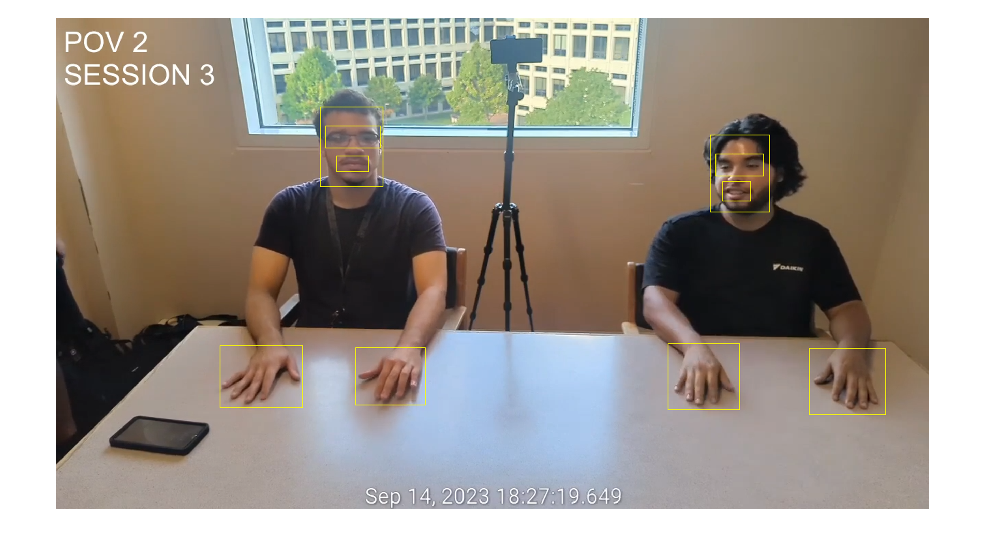

data = read(trainingData);
I = data{1};
bbox = data{2};
annotatedImage = insertShape(I,'rectangle',bbox);
annotatedImage = imresize(annotatedImage,2);
figure
imshow(annotatedImage)

## Create a custom YOLO v2 Object Detection Network

Set the input size for our network down to 416 x 416 to improve calculation time. 

inputSize = [416 416 3];

Define the number of object classes to detect.

numClasses = width(projectDataset)-1;

Resize our training data images so that we can estimate anchors for detection

trainingDataForEstimation = transform(trainingData,@(data)preprocessData(data,inputSize));

Set number of anchors to 8 and use the estimate function to get the best estimates for detection anchors

numAnchors = 8;
[anchorBoxes, meanIoU] = estimateAnchorBoxes(trainingDataForEstimation, numAnchors);

We're using `resnet50` to load a pretrained ResNet-50 model to use feature extraction and train our own network

featureExtractionNetwork = resnet50;

Select `'activation_40_relu'` as the feature extraction layer to replace the layers after `'activation_40_relu'` with our own detection subnetwork. 

featureLayer = 'activation_40_relu';

Create the YOLO v2 object detection network. 

lgraph = yolov2Layers(inputSize,numClasses,anchorBoxes,featureExtractionNetwork,featureLayer);

## Data Augmentation

We use data augmentation which randomly transforms the original data during training to increase network accuracy. This allows us to add more variety to the training data without the need to actually collect more traning data.

augmentedTrainingData = transform(trainingData,@augmentData);

Read the same image multiple times and display the augmented training data.

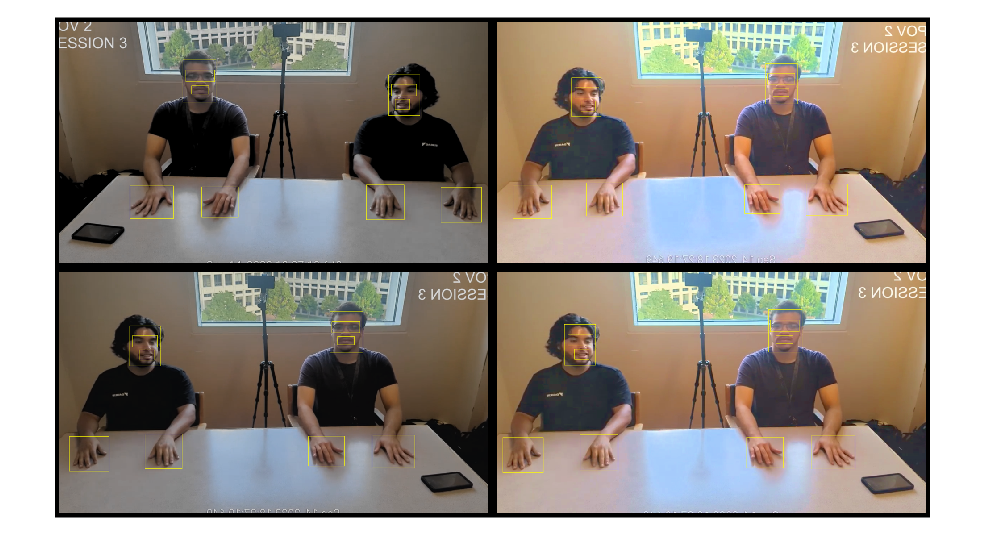

% Visualize the augmented images.
augmentedData = cell(4,1);
for k = 1:4
    data = read(augmentedTrainingData);
    augmentedData{k} = insertShape(data{1},'rectangle',data{2});
    reset(augmentedTrainingData);
end
figure
montage(augmentedData,'BorderSize',10)

## Preprocess Training Data

Preprocess the augmented training data, and the validation data to prepare for training. During this preprocessing step we're just scaling the images to the proper input size because that is what our network is designed to use.

preprocessedTrainingData = transform(augmentedTrainingData,@(data)preprocessData(data,inputSize));
preprocessedValidationData = transform(validationData,@(data)preprocessData(data,inputSize));

Read the preprocessed training data.

data = read(preprocessedTrainingData);

Display the image and bounding boxes.

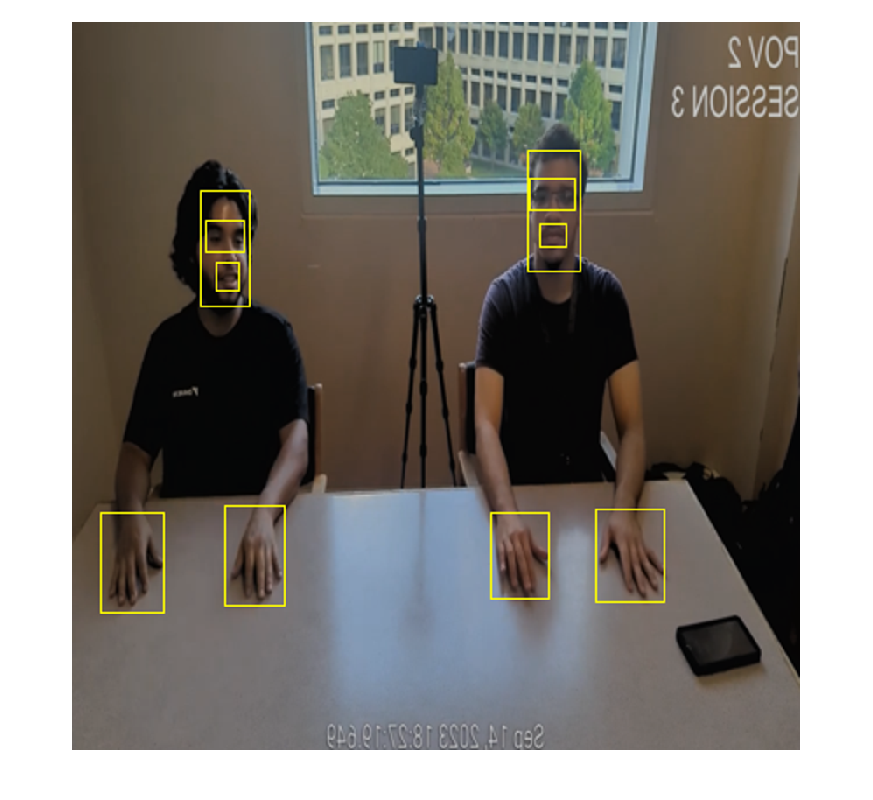

I = data{1};
bbox = data{2};
annotatedImage = insertShape(I,'rectangle',bbox);
annotatedImage = imresize(annotatedImage,2);
figure
imshow(annotatedImage)

## Train YOLO v2 Object Detector

Set options for detection trainer. Creating a checkpoint path incase the process gets interrupted and the validation data to keep the training from going off the rails.

options = trainingOptions('sgdm', ...
        'MiniBatchSize',10, ....
        'InitialLearnRate',1e-3, ...
        'MaxEpochs',16, ... 
        'CheckpointPath',tempdir, ...
        'ValidationData',preprocessedValidationData);

Use [`trainYOLOv2ObjectDetector`](docid:vision_ref#mw_0ff9d26a-9a79-4333-a1b1-ba03c8539ee3) function to train YOLO v2 object detector.

[detector,info] = trainYOLOv2ObjectDetector(preprocessedTrainingData,lgraph,options);

*************************************************************************
Training a YOLO v2 Object Detector for the following object classes:

* Hands
* Eyes
* Face
* Mouth

Training on single GPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:12 |         6.32 |         3.07 |      39.9214 |       9.4269 |          0.0010 |
|       1 |          50 |       00:01:04 |         0.65 |         0.65 |       0.4244 |       0.4257 |          0.0010 |
|       1 |         100 |       00:0

As a quick test, run the detector on a test image. Make sure you resize the image to the same size as the training images.

I = imread("Barnes, Duncan Allen - frames\Session 3\Dataset\session3_pov33_0241.png");
I = imresize(I,inputSize(1:2));
[bboxes,scores] = detect(detector,I, "Threshold", 0.4);

Display the results.

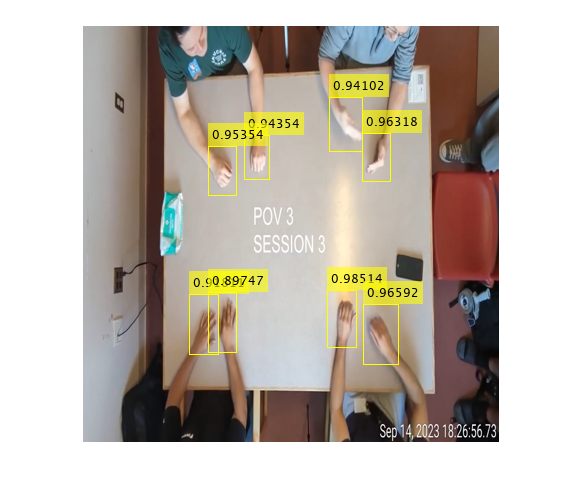

I = insertObjectAnnotation(I,'rectangle',bboxes,scores);
figure
imshow(I)

## Evaluate Detector Using Test Set

In order to test our detector we must first preprocess the test data in the same way we did the traininig and validation data.

preprocessedTestData = transform(testData,@(data)preprocessData(data,inputSize));

Run the detector on all the test images.

detectionResults = detect(detector, preprocessedTestData);

Evaluate the object detector using average precision metric.

metrics = evaluateObjectDetection(detectionResults,preprocessedTestData);
classID = 1;
precision = metrics.ClassMetrics.Precision{classID};
recall = metrics.ClassMetrics.Recall{classID};

Plot the PR curve which gives a general idea of accuracy

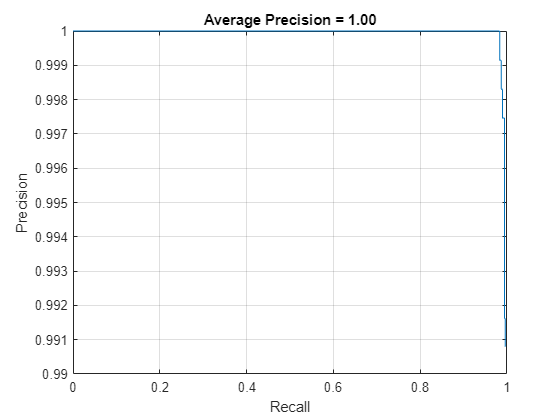

figure
plot(recall,precision)
xlabel('Recall')
ylabel('Precision')
grid on
title(sprintf('Average Precision = %.2f',metrics.ClassMetrics.mAP(classID)))

Save detector

save("yoloDetector_successful.mat", "detector");

## Supporting Functions

These supporting functions were provided from the Yolo v2 Vehicle recognition tutorial in Matlab.

function B = augmentData(A)
% Apply random horizontal flipping, and random X/Y scaling. Boxes that get
% scaled outside the bounds are clipped if the overlap is above 0.25. Also,
% jitter image color.

B = cell(size(A));

I = A{1};
sz = size(I);
if numel(sz)==3 && sz(3) == 3
    I = jitterColorHSV(I,...
        'Contrast',0.2,...
        'Hue',0,...
        'Saturation',0.1,...
        'Brightness',0.2);
end

% Randomly flip and scale image.
tform = randomAffine2d('XReflection',true,'Scale',[1 1.1]);
rout = affineOutputView(sz,tform,'BoundsStyle','CenterOutput');
B{1} = imwarp(I,tform,'OutputView',rout);

% Sanitize boxes, if needed. This helper function is attached as a
% supporting file. Open the example in MATLAB to access this function.
%A{2} = helperSanitizeBoxes(A{2});

% Apply same transform to boxes.
[B{2},indices] = bboxwarp(A{2},tform,rout,'OverlapThreshold',0.25);
B{3} = A{3}(indices);

% Return original data only when all boxes are removed by warping.
if isempty(indices)
    B = A;
end
end

function data = preprocessData(data,targetSize)
% Resize image and bounding boxes to the targetSize.
sz = size(data{1},[1 2]);
scale = targetSize(1:2)./sz;
data{1} = imresize(data{1},targetSize(1:2));

% Sanitize boxes, if needed. This helper function is attached as a
% supporting file. Open the example in MATLAB to access this function.
%data{2} = helperSanitizeBoxes(data{2});

% Resize boxes to new image size.
data{2} = bboxresize(data{2},scale);
end